Note, the runtimes change a bit each time the script is run. But the relative comparisons stay similar.

clear,close all
x = linspace(0,100,1e8);

No initialization for loop

tic
for i = 1:length(x)
    y(i) = x(i);
end
noInitFor = toc;

Initialization for loop

clear y
tic
y = zeros(1,numel(x));
for i = 1:length(x)
    y(i) = x(i);
end
initFor = toc;

For each-ish loop

clear y
tic
for value = x
    y = value;
end
eachIsh = toc;

Direct assignment

tic
y = x;
direct = toc;

Plot them up to compare

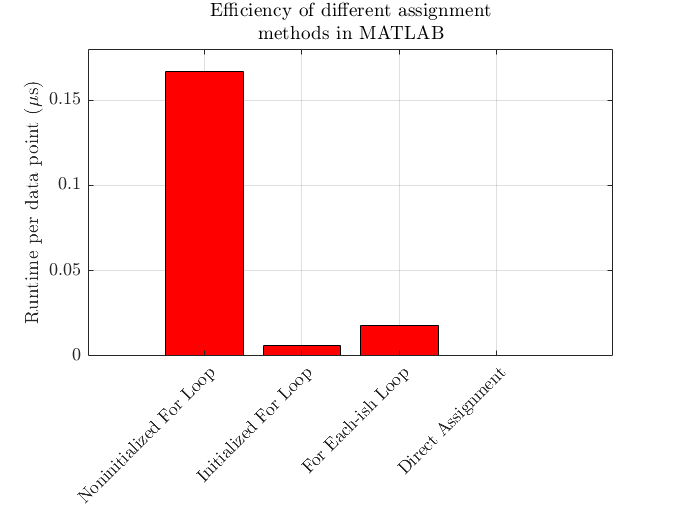

bar([noInitFor,initFor,eachIsh,direct]./length(x).*1e6)
ylabel("Runtime per data point ($\mu$s)")
title(["Efficiency of different assignment", "methods in MATLAB"])
grid on
h = gca;
h.XTickLabel = ["Noninitialized For Loop","Initialized For Loop","For Each-ish Loop","Direct Assignment"];
h.XTickLabelRotation = 45;